================================================================================

# Práctica 12. EDOs

#### Problema 1. Métodos de Euler en el sistema masa-resorte-amortiguador (MRA)

Consideramos el clásico sistema físico con una masa $m$ conectada a un muelle o resorte con constante elástica $k$ y un amortiguador con coeficiente de amortiguamiento $c$: 

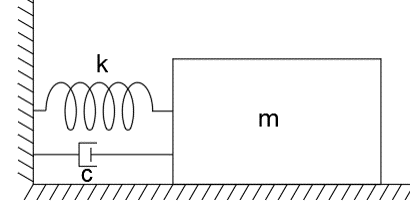

La ecuación del movimiento de la masa (sin rozamiento) viene dada por ${\displaystyle m{\ddot {x}} = -kx-c{\dot {x}}}$.

Es común escribir esta ecuación usando otras parámetros que ayudan mejor a entender el comportamiento del sistema, concretamente la frecuencia natural $\omega_N = \sqrt{\frac{k}{m}}$ y el factor de amortiguación $\zeta = \frac{c}{2\sqrt{km}}$. Con ellos, la ecuación del movimiento es:

$\ddot x + 2\zeta \omega_N \dot x + \omega_N ^2 x = 0$.

Para este ejercicio asumimos $\omega_N =3\pi$ y $\zeta=0.3$.

- Transformar a mano la ecuación del movimiento en un sistema de EDOs de primer orden. Escribir una función anónima para la ecuación del movimiento de orden dos y usar la función $\texttt{odeToVectorField()}$ para comprobar los resultados. Observar que el sistema de EDOs es lineal y autónomo. Escribir la matriz del sistema $A$.

clear all


$$dy1 = y_{2}$$

$$dy2 = -\frac{3125302502557517\,y_{1}}{35184372088832}-\frac{9\,\pi \,y_{2}}{5}$$

$$sist = \left(\begin{array}{c} Y_{2}\\ -\frac{9\,\pi \,Y_{2}}{5}-\frac{3125302502557517\,Y_{1}}{35184372088832} \end{array}\right)$$

A =                    0   1.000000000000000
 -88.826439609804225  -5.654866776461628


- Dibujar el campo vectorial resultante con la función $\texttt{quiver()}$ de MATLAB. Para ello grear una malla $\texttt{meshgrid(-2:0.1:2, -20:1.2:15)}$.

%[X, Y] = meshgrid(-2:0.1:2, -20:1.2:15);


Consideramos el PVI con condiciones iniciales $x(0) = 2$ y $\dot x (0) = 0$. Buscamos la trayectora en el intervalo de tiempo $[0, 8]$.

- Integrar (encontrar la trayectoria) usando la fórmula de Euler explícita con $h=0.05$ (crear esta variable `h` y trabajar con ella de manera que se pueda modificar). Dibujar la posición $x$ frente a la velocidad $\dot x$ de la solución sobre el campo vectorial.

- Hacer una representación gráfica de $x$ en el tiempo en rojo.

- Encontrar la solución ahora usando la fórmula de Euler implícita (con la misma $h$). Añadir a la gráfica anterior esta solución en verde.

- Encontrar la (mejor) solución que da Matlab con la función $\texttt{ode45()}$ y añadira a la gráfica en negro.

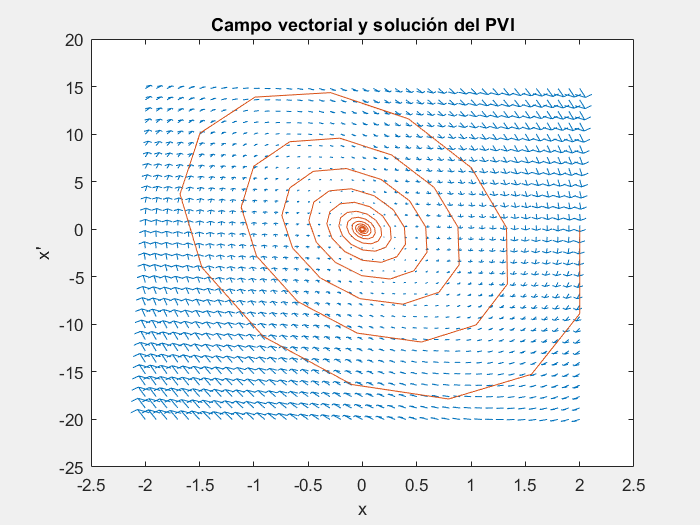

yEe =    2.000000000000000                   0
   2.000000000000000  -8.882643960980422
   1.555867801950979 -15.253779510856560
   0.793178826408151 -17.850984829827741
  -0.099370415083236 -16.326500333948022
  -0.915695431780638 -11.268955109511793
  -1.479143187256227  -4.015834868199187
  -1.679934930666187   3.688966840451030
  -1.495486588643635  10.107067972535306
  -0.990133190016870  13.891299285940141


- Observar qué sucede cuando cambiamos $h=0.001$ y $h = 0.1$. ¿Qué está pasando?

#### Problema 2. Método de Runge-Kutta RK4

Implementar el método RK4 para una EDO $\dot y = f(t,y)$. La función debe tomar como argumentos:

- la función $f$, 

- el valor inicial $y(t_0)$,

- el paso $h$ para el método,

- el intervalo de integración $[t_0,t_{max}]$

Y debe devolver la solución discretizada (trayectoria) y, si se quiere, la discretización de $t$ usada.

Consideramos los siguientes PVIs:

- $y' = -y + t + 1, \quad 0 \leq t \leq 1, \quad y(0) = 1$,

- $y' = te^{3t} - 2y, \quad 0 \leq t \leq 1, \quad y(0) = 0$,

- $y' = \cos(2t) + sin(3t), \quad 0\leq t\leq 1, \quad y(0) = 1$.

Para cada uno de ellos calculamos la solución con $t\in[0,1]$ usando tres métodos:

-  La implementación realizada de $\texttt{RK4}$.

-  La función$\texttt{ode45}$de MATLAB.

-  La solución analítica con la función `dsolve` de MATLAB o con las soluciones analíticas siguienetes, respectivamente:

$y(t) = e^{-t} + t$,

$y(t) = \frac15 t e^{3t} - \frac{1}{25}e^{3t} + \frac{1}{25}e^{-2t}$,

$y(t) = \frac12 \sin(2t) - \frac13 \cos(3t) + \frac43$.

Representar gráficamente la solución analítica (continua) y las soluciones con $\texttt{RK4}$ y $\texttt{ode45}$ con asteriscos de distintos colores. 

Para comparar más a fondo los métodos, calcular el error absoluto entre las soluciones obtenidas por $\texttt{RK4}$ y $\texttt{ode45}$ y la solución analítica. Hacer un gráfico que muestre los errores de cada una de las tres fórmulas.

clear all
format long


#### Funciones internas

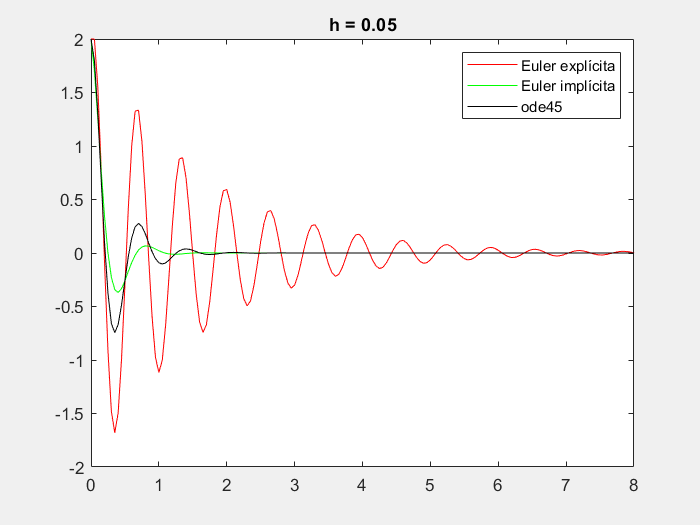

t =                    0
   0.050000000000000
   0.100000000000000
   0.150000000000000
   0.200000000000000
   0.250000000000000
   0.300000000000000
   0.350000000000000
   0.400000000000000
   0.450000000000000


yMatlab =    2.000000000000000                   0
   1.800756113850447  -7.456332700348387
   1.309084128679579 -11.656036302938004
   0.689414963923974 -12.608477985830817
   0.092237720801198 -10.933989821531695
  -0.375864383775181  -7.594158967395527
  -0.657003639409723  -3.636892152317186
  -0.744280974351968   0.036384917323358
  -0.668644989567461   2.797821230172334
  -0.484847399079850   4.347473677372724


t =                    0
   0.001000000000000
   0.002000000000000
   0.003000000000000
   0.004000000000000
   0.005000000000000
   0.006000000000000
   0.007000000000000
   0.008000000000000
   0.009000000000000


yMatlab =    2.000000000000000                   0
   1.999911452614610  -0.176815715924840
   1.999646926615425  -0.351957178977873
   1.999208096232548  -0.525424611200507
   1.998596635316273  -0.697218379754263
   1.997814213856452  -0.867338966011855
   1.996862493472547  -1.035786926395154
   1.995743151932308  -1.202563109167100
   1.994457866566530  -1.367668505776249
   1.993008312255121  -1.531104232927553


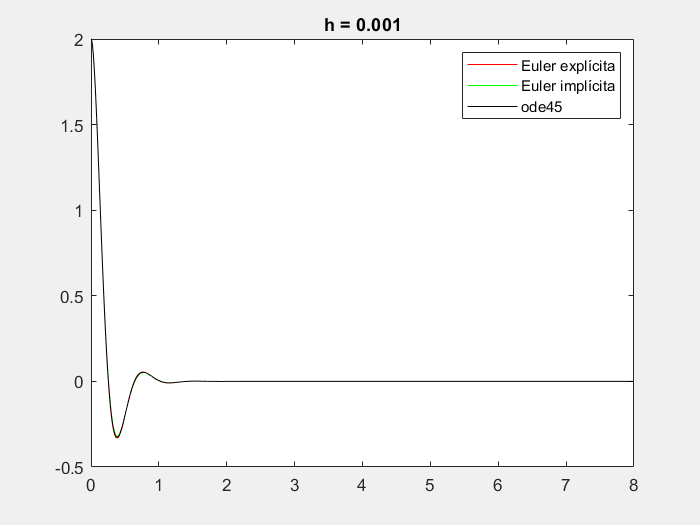

t =                    0
   0.100000000000000
   0.200000000000000
   0.300000000000000
   0.400000000000000
   0.500000000000000
   0.600000000000000
   0.700000000000000
   0.800000000000000
   0.900000000000000


yMatlab =    2.000000000000000                   0
   1.309084128679579 -11.656036302938004
   0.092237720801198 -10.933989821531695
  -0.657003639409723  -3.636892152317186
  -0.668644989567461   2.797821230172334
  -0.254048753931051   4.690295242387287
   0.141368677866737   2.811096690064144
   0.276960138973625  -0.026371070990964
   0.179543042856906  -1.621555228079014
   0.011125680526126  -1.505998861074785


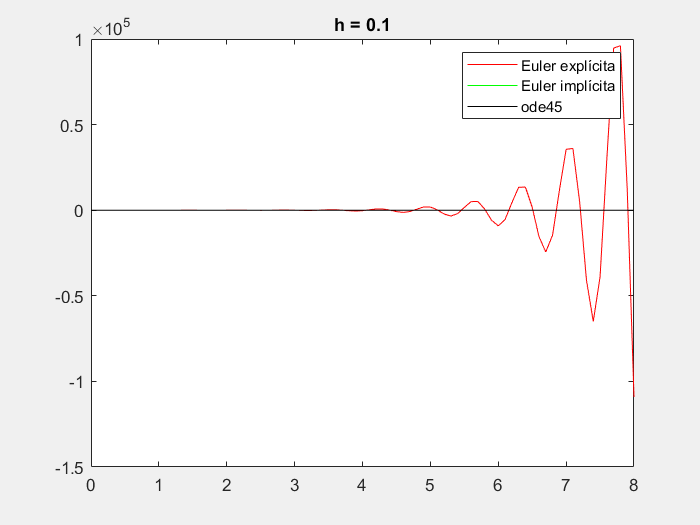

`Documento preparado por I. Parada, 22 de mayo de 2024`